data = readtable('electricity.xlsx','Sheet',1,'Range','B2:B13');

%'Delimiter','\t'  % not necessary for excel files

[num,txt] = xlsread('electricity.xlsx');

data = readtable('electricity.xlsx');

%data{:,2:5}

sectors = data.Properties.VariableNames(2:end)

sectors =     'Residential'    'Commercial'    'Industrial'    'Total'

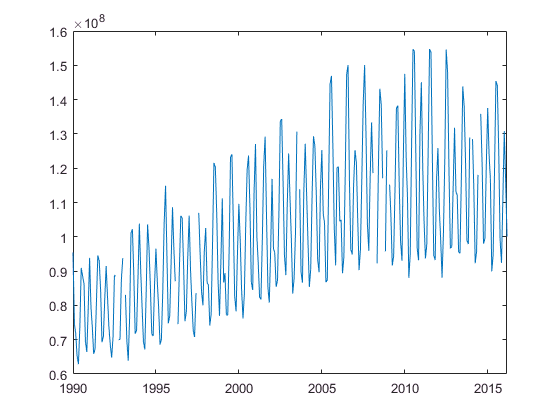


usage = data{:,sectors};
dates = data.Date;
residental = data.Residential;

plot(dates,residental)

% make time a uniform variable

dates(end)

ans =    3/1/2016

calmonths(1)

ans =    1mo

nextmonth = dates(end) + calmonths(1)

nextmonth =    4/1/2016


datesplus1 = [dates;nextmonth]

datesplus1 =    1/1/1990 
   2/1/1990 
   3/1/1990 
   4/1/1990 
   5/1/1990 
   6/1/1990 
   7/1/1990 
   8/1/1990 
   9/1/1990 
   10/1/1990
   11/1/1990
   12/1/1990
   1/1/1991 
   2/1/1991 
   3/1/1991 
   4/1/1991 
   5/1/1991 
   6/1/1991 
   7/1/1991 
   8/1/1991 
   9/1/1991 
   10/1/1991
   11/1/1991
   12/1/1991
   1/1/1992 
   2/1/1992 
   3/1/1992 
   4/1/1992 
   5/1/1992 
   6/1/1992 
   7/1/1992 
   8/1/1992 
   9/1/1992 
   10/1/1992
   11/1/1992
   12/1/1992
   1/1/1993 
   2/1/1993 
   3/1/1993 
   4/1/1993 
   5/1/1993 
   6/1/1993 
   7/1/1993 
   8/1/1993 
   9/1/1993 
   10/1/1993
   11/1/1993
   12/1/1993
   1/1/1994 
   2/1/1994 
   3/1/1994 
   4/1/1994 
   5/1/1994 
   6/1/1994 
   7/1/1994 
   8/1/1994 
   9/1/1994 
   10/1/1994
   11/1/1994
   12/1/1994
   1/1/1995 
   2/1/1995 
   3/1/1995 
   4/1/1995 
   5/1/1995 
   6/1/1995 
   7/1/1995 
   8/1/1995 
   9/1/1995 
   10/1/1995
   11/1/1995
   12/1/1995
   1/1/1996 
   2/1/1996 
   3/1/1996 
   4/1/1996 


dur = diff(datesplus1)

dur =    744:00:00
   672:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   672:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   696:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   672:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   672:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   672:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   696:00:00
   744:00:00
   720:00:00
   744


daysPerMonth = days(dur)

daysPerMonth =     31
    28
    31
    30
    31
    30
    31
    31
    30
    31

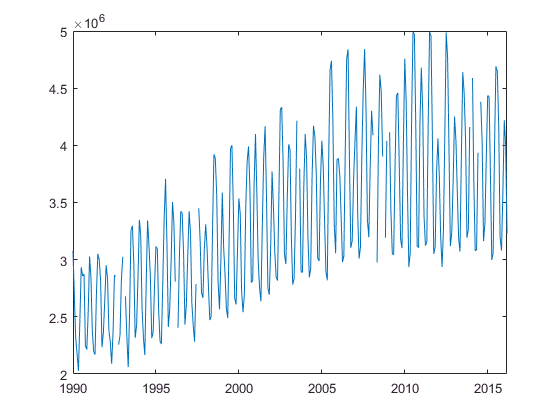


NormResidential = residental./daysPerMonth;

plot(dates,NormResidential)

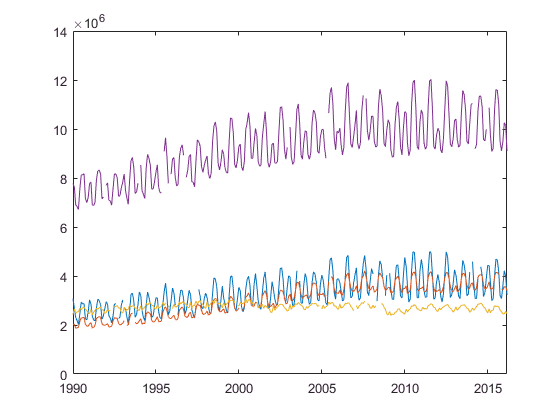

usage = usage./daysPerMonth;

plot(dates,usage)

% subtract mean, divide by std
zusage = zscore(usage)

zusage =    NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN


idx = ~any(isnan(usage),2)

idx =    1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   0
   1
   1
   1
   0
   1
   1
   1
   1
   0
   0
   1
   1
   1
   1
   1
   0
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   0
   1
   0
   0
   1
   1
   1
   0
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   0
   0
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


zusage = zscore(usage(idx,:))

zusage =    -0.3865   -1.5816   -2.2347   -1.2206
   -0.9929   -1.5561   -0.5146   -1.3429
   -1.4887   -1.8072   -1.8508   -1.9256
   -1.7014   -1.7880   -1.4012   -1.9824
   -1.9115   -1.7592   -1.4060   -2.0812
   -1.2796   -1.3688   -0.3370   -1.3853
   -0.5967   -1.1598   -0.8589   -0.9388
   -0.7078   -1.1513   -0.1793   -0.9251
   -0.6820   -1.1270   -0.1128   -0.8924
   -1.5968   -1.5517   -0.6633   -1.7089

% removed missing data to normalize

ridx = isnan(usage(:,1))


mean(usage,'omitnan')

ans =    1.0e+06 *
    3.3473    3.0386    2.7352    9.2823

nnz(isnan(usage))

ans = 37

sum(isnan(usage))

ans =     11     6    10    10

idx = ~any(ismissing(data),2) %for table

idx =    1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   0
   1
   1
   1
   0
   1
   1
   1
   1
   0
   0
   1
   1
   1
   1
   1
   0
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   0
   1
   0
   0
   1
   1
   1
   0
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   0
   0
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1

x = [1 2 3 nan 4 nan 7]

x =      1     2     3   NaN     4   NaN     7

[y,idx] = rmmissing(x)

y =      1     2     3     4     7

idx =    0   0   0   1   0   1   0


resUsage = usage(:,1);
resUsageOK = rmmissing(resUsage)

resUsageOK =    1.0e+06 *
    3.0781
    2.6607
    2.3194
    2.1730
    2.0284
    2.4633
    2.9334
    2.8569
    2.8747
    2.2450

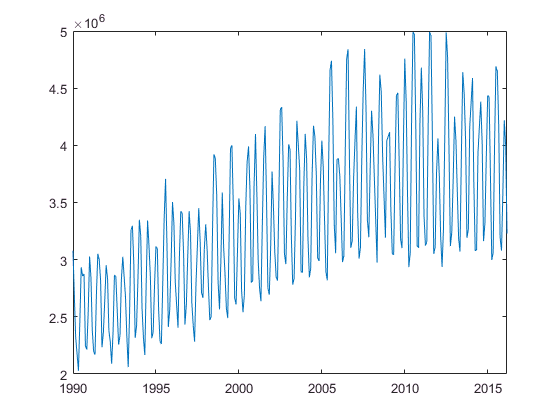


% plot(dates,resUsageOK)

idxOK = ~ismissing(resUsage);
datesOK = dates(idxOK);

plot(datesOK,resUsageOK)

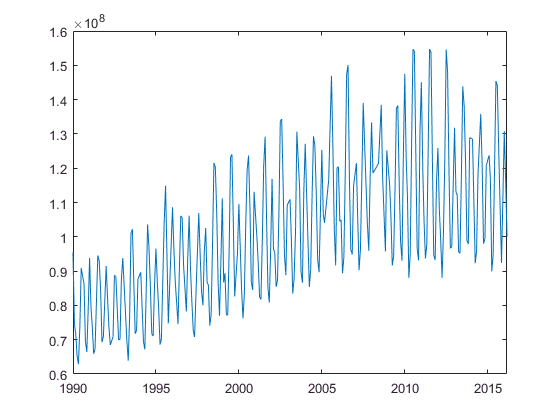

dataOK = rmmissing(data); %table
plot(dataOK.Date,dataOK.Residential)

resUsage(~idxOK) = []; %delete



resUsage = usage(:,1);

plot(dates,resUsage)

% interpolation
eqfill = fillmissing(resUsage,'linear')

eqfill =    1.0e+06 *
    3.0781
    2.6607
    2.3194
    2.1730
    2.0284
    2.4633
    2.9334
    2.8569
    2.8747
    2.2450


linfill = fillmissing(resUsage,'spline',...
    'SamplePoints',dates)

linfill =    1.0e+06 *
    3.0781
    2.6607
    2.3194
    2.1730
    2.0284
    2.4633
    2.9334
    2.8569
    2.8747
    2.2450

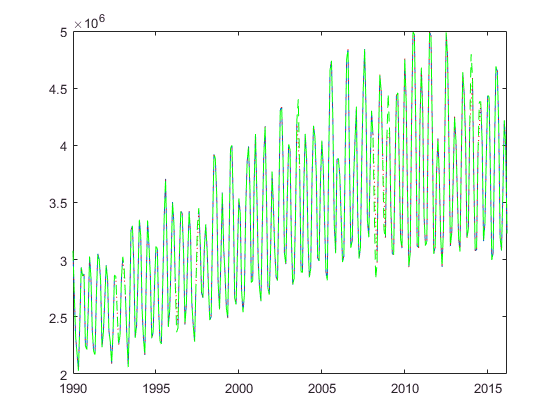


hold on
plot(dates,eqfill,'r:')

plot(dates,linfill,'g--')

hold off

corrcoef(usage(:,1:3),'rows','complete')

ans =     1.0000    0.8237    0.1390
    0.8237    1.0000    0.1620
    0.1390    0.1620    1.0000


corrcoef(usage(:,1:3),'rows','pairwise')

ans =     1.0000    0.8242    0.1462
    0.8242    1.0000    0.1535
    0.1462    0.1535    1.0000

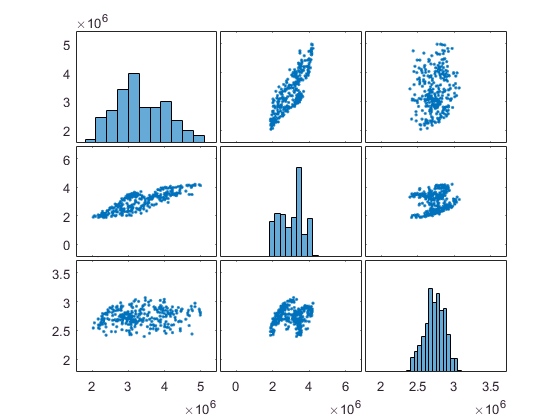


plotmatrix(usage(:,1:3))

usageF = fillmissing(usage,'spline',...
    'SamplePoints',dates)

usageF =    1.0e+06 *
    3.0781    2.0161    2.4254    7.7702
    2.6607    2.0326    2.6645    7.6201
    2.3194    1.8703    2.4788    6.9054
    2.1730    1.8827    2.5413    6.8357
    2.0284    1.9013    2.5406    6.7146
    2.4633    2.1536    2.6892    7.5681
    2.9334    2.2886    2.6167    8.1158
    2.8569    2.2942    2.7111    8.1327
    2.8747    2.3099    2.7204    8.1727
    2.2450    2.0354    2.6438    7.1712

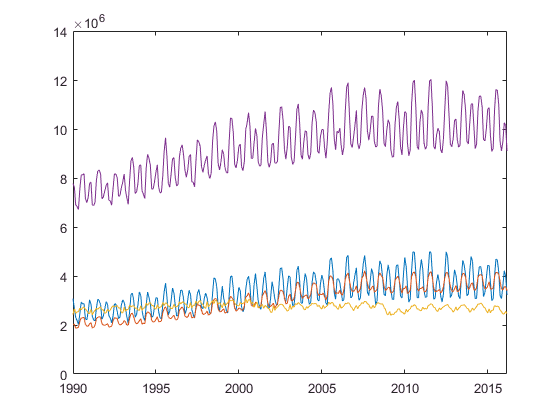



plot(dates,usageF)

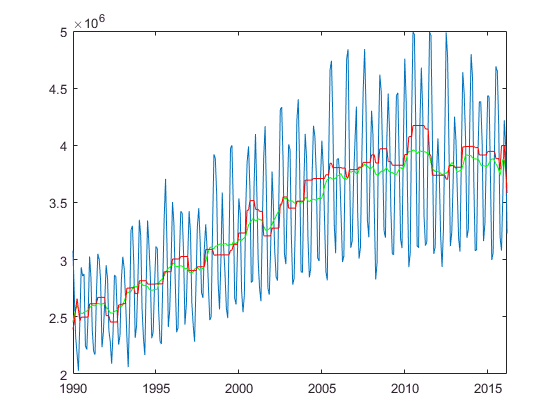


ResUsage = usageF(:,1);
plot(dates,ResUsage)


usageMovAvg = movmean(ResUsage,12);
usageMovMed = movmedian(ResUsage,12);
hold on
plot(dates,usageMovAvg,'g-')
plot(dates,usageMovMed,'r-')
hold off

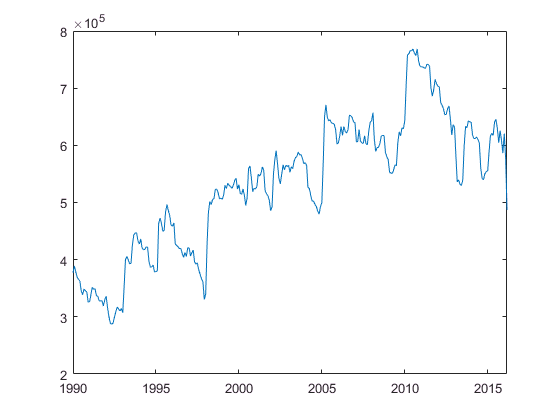


usageStdAvg = movstd(ResUsage,12);
plot(dates,usageStdAvg)

n = 100;

elapsedYears = years(dates - dates(1));
c = polyfit(elapsedYears(n:end),ResUsage(n:end),3)

c =    1.0e+06 *
   -0.0001    0.0011    0.1045    2.1643

c(1)

ans = -104.4665

y = polyval(c,elapsedYears(n:end));

future = polyval(c,elapsedYears(end)+10)

future = 2.3992e+06

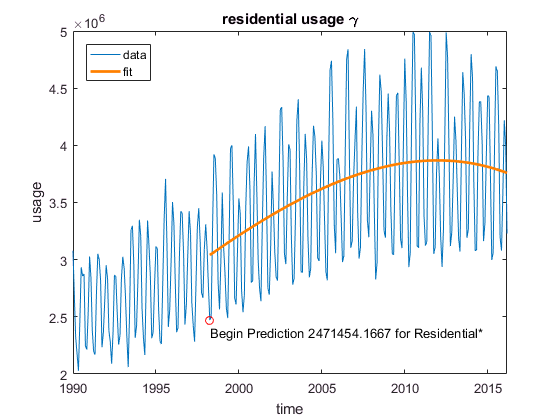


plot(dates,ResUsage)
hold on
plot(dates(n:end),y,'color',[1 0.5 0],'Linewidth',2)
plot(dates(100),ResUsage(100),'ro')
ourlabel = ['Begin Prediction ',num2str(ResUsage(100)),' for Residential', 163];
text(dates(100),ResUsage(100)-1e5,ourlabel)
hold off

xlabel('time')
ylabel('usage')
title('residential usage \gamma')
legend('data','fit','location','NW')

% fitlm

mdl = fitlm(elapsedYears,ResUsage)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE      tStat       pValue   
                   _________    ______    ______    ___________
    (Intercept)    2.577e+06     60398    42.667    1.7297e-132
    x1                 59326    3995.2    14.849     3.9751e-38

Number of observations: 315, Error degrees of freedom: 313
Root Mean Squared Error: 5.37e+05
R-squared: 0.413,  Adjusted R-Squared 0.411
F-statistic vs. constant model: 221, p-value = 3.98e-38


% fitdist




